usage: teamwork for week 4

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.3.29

%clear all; close all; clc

**小组作业**

**1. 编写程序，按照下式计算常数**$e$**，**


$$e=\lim_{n\rightarrow\infty}\left(1+\frac{1}{n}\right)^n——(1)$$


**a) 对**$n=10^{(1,2,\dots ,20)}$**，进行计算。**

**b) 将结果和内部函数exp(1)比较，确定近似值的误差。**

**c) 误差是否随**$n$**的增加而降低？请画出误差的变化趋势曲线。**

解：

a）

%公式1
calculate_e = @(x) (1+ones(size(x))./x).^x

calculate_e = 包含以下值的 function_handle :
    @(x)(1+ones(size(x))./x).^x


% a为当n=10^(1,2,...,20)的计算结果
a = calculate_e(10.^(1:20))

a =    2.5937e+00   2.7048e+00   2.7169e+00   2.7181e+00   2.7183e+00   2.7183e+00   2.7183e+00   2.7183e+00   2.7183e+00   2.7183e+00   2.7183e+00   2.7185e+00   2.7161e+00   2.7161e+00   3.0350e+00   1.0000e+00   1.0000e+00   1.0000e+00   1.0000e+00   1.0000e+00


b）

近似值的绝对误差（由于相对误差与绝对误差只相差$exp(1)$倍，总体趋势不变，故无需计算）

e = absolute_e(a, exp(1))

e =   -1.2454e-01  -1.3468e-02  -1.3579e-03  -1.3590e-04  -1.3591e-05  -1.3594e-06  -1.3433e-07  -3.0112e-08   2.2355e-07   2.2478e-07   2.2490e-07   2.4167e-04  -2.1718e-03  -2.1718e-03   3.1675e-01  -1.7183e+00  -1.7183e+00  -1.7183e+00  -1.7183e+00  -1.7183e+00


c）

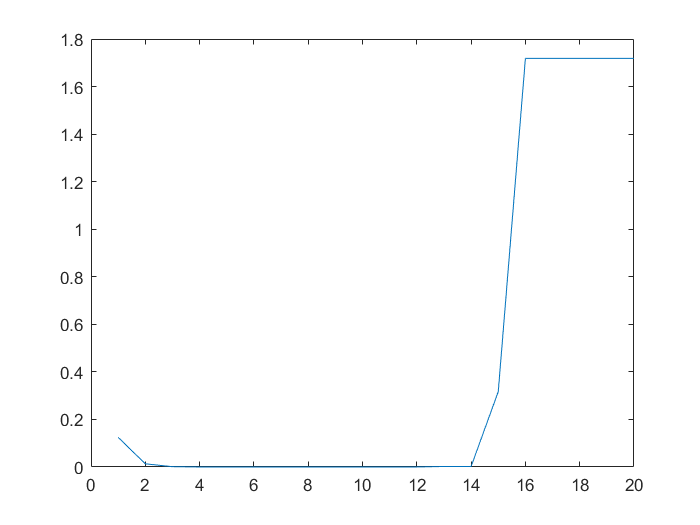

plot(1:20, abs(e))

由图可知，绝对误差的绝对值在$$1\le n \le10$$逐渐降低，当$n>10$由于舍入误差而升高。

**2. 可以证明**


$$\pi=4\sum\limits_{k=1}^\infty \frac{(-1)^{k-1}}{2k-1}$$


**请自定义函数my_pi， 以正整数**$n$**为变量， 计算有限项求和**


$$4\sum\limits_{k=1}^n \frac{(-1)^{k-1}}{2k-1}——(2)$$


**分别取**$$n=10, 20, 40$$**， 打印出结果从而证明等式成立，并求出相对误差。**

解：

%公式2
n = [10 20 40]

n =     10    20    40


p = my_pi(n)

p =    3.0418e+00   3.0916e+00   3.1166e+00


%计算所得pi的相对误差:
e_r_p = relative_e(p, pi)

e_r_p =   -3.1752e-02  -1.5906e-02  -7.9565e-03


%进一步验证等式成立
more_n = 40:20:1000

more_n =           40          60          80         100         120         140         160         180         200         220         240         260         280         300         320         340         360         380         400         420         440         460         480         500         520         540         560         580         600         620         640         660         680         700         720         740         760         780         800         820         840         860         880         900         920         940         960         980        1000


more_p = my_pi(more_n)

more_p =    3.1166e+00   3.1249e+00   3.1291e+00   3.1316e+00   3.1333e+00   3.1344e+00   3.1353e+00   3.1360e+00   3.1366e+00   3.1370e+00   3.1374e+00   3.1377e+00   3.1380e+00   3.1383e+00   3.1385e+00   3.1387e+00   3.1388e+00   3.1390e+00   3.1391e+00   3.1392e+00   3.1393e+00   3.1394e+00   3.1395e+00   3.1396e+00   3.1397e+00   3.1397e+00   3.1398e+00   3.1399e+00   3.1399e+00   3.1400e+00   3.1400e+00   3.1401e+00   3.1401e+00   3.1402e+00   3.1402e+00   3.1402e+00   3.1403e+00   3.1403e+00   3.1403e+00   3.1404e+00   3.1404e+00   3.1404e+00   3.1405e+00   3.1405e+00   3.1405e+00   3.1405e+00   3.1406e+00   3.1406e+00   3.1406e+00


e_r_more_p = relative_e(more_p, pi)

e_r_more_p =   -7.9565e-03  -5.3048e-03  -3.9787e-03  -3.1830e-03  -2.6525e-03  -2.2736e-03  -1.9894e-03  -1.7684e-03  -1.5915e-03  -1.4469e-03  -1.3263e-03  -1.2243e-03  -1.1368e-03  -1.0610e-03  -9.9472e-04  -9.3620e-04  -8.8419e-04  -8.3766e-04  -7.9577e-04  -7.5788e-04  -7.2343e-04  -6.9198e-04  -6.6314e-04  -6.3662e-04  -6.1213e-04  -5.8946e-04  -5.6841e-04  -5.4881e-04  -5.3052e-04  -5.1340e-04  -4.9736e-04  -4.8229e-04  -4.6810e-04  -4.5473e-04  -4.4210e-04  -4.3015e-04  -4.1883e-04  -4.0809e-04  -3.9789e-04  -3.8818e-04  -3.7894e-04  -3.7013e-04  -3.6172e-04  -3.5368e-04  -3.4599e-04  -3.3863e-04  -3.3157e-04  -3.2481e-04  -3.1831e-04


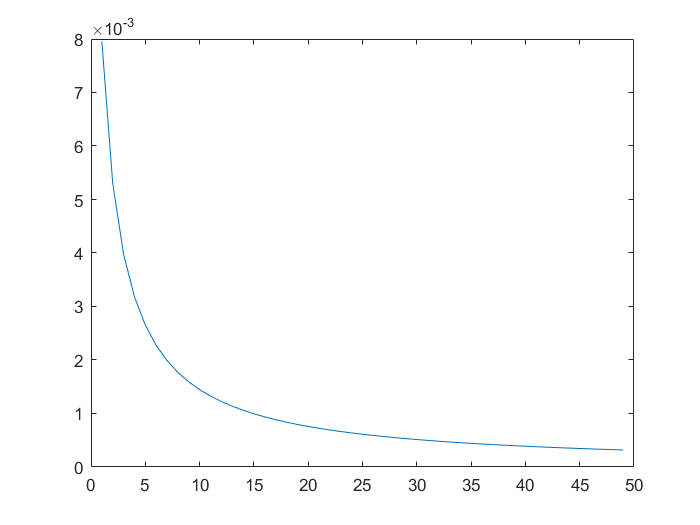

plot(1:length(e_r_more_p),abs(e_r_more_p))

由图可知，当$n\to\infty$，相对误差越来越小，结果会越接近于$\pi$，等式是成立的。

**3. 编写程序，用无穷级数计算指数函数**


$$e^x=1+x+\frac{x^2}{2!}+\frac{x^3}{3!}+\cdots ——(3)$$


**a) 若按自然顺序求和，应用什么判停标准？**

**b) 用**$x=\pm 1, \pm 5, \pm 10,  \pm 15, \pm 20$**测试程序，将内部函数**$$\exp(x)$$**的结果作为准确值，评估计算结果的误差。**

**c) 当**$$x<0$$**时，能否通过此程序得到准确的结果？能否通过级数项的重新排列或分组得到较准确的结果?  请设法改进你的程序。**

解：

a）用无穷级数与准确值的差的绝对值是否满足预定精度，或达到最多计算项数时停止（由于计算精度，可能无法达到预定精度），作为判停标准。

b）

x = [-20 -15 -10 -5 -1 1 5 10 15 20]

x =    -20   -15   -10    -5    -1     1     5    10    15    20


e_x = my_e_x(x, 1e-6, 100)

e_x = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0327    4.8516


e_r_e_x = relative_e(e_x, exp(x))

e_r_e_x =     1.7275    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


fprintf('my_e_x\t\texp(x)\t\te_r_e_x\n===========================================\n')

my_e_x		exp(x)		e_r_e_x


for k=1:length(x)
    fprintf('%f\t%f\t%f\n', e_x(k), exp(x(k)), e_r_e_x(k))
end

0.000000	0.000000	1.727543
0.000000	0.000000	0.000023
0.000045	0.000045	-0.000001
0.006738	0.006738	-0.000000
0.367879	0.367879	-0.000001
2.718282	2.718282	-0.000000
148.413108	148.413159	-0.000000
22026.448956	22026.465795	-0.000001
3269015.859346	3269017.372472	-0.000000
485164975.136088	485165195.409790	-0.000000


当$x>-10$时，级数计算结果与准确值的结果相对误差小于$1\%$，误差较小；

当$x\le-10$时，$x$越小级数计算结果误差越大。

c）

当$x<0$时，使用原程序不能得到较为准确的结果。

由级数项一正一负且随级数项的增加，正负两项和不断减小，故当$x<0$时，使用从最大求和项开始，将正负两项相加后，倒序求和。

x = [-20 -15 -10 -5 -1 1 5 10 15 20]

x =    -20   -15   -10    -5    -1     1     5    10    15    20


e_x = my_e_x_improve1(x, 1e-6, 100)

e_x = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0327    4.8517


e_r_e_x = relative_e(e_x, exp(x))

e_r_e_x =     1.1801    0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


fprintf('my_e_x\t\texp(x)\t\te_r_e_x_improve1\n===========================================\n')

my_e_x		exp(x)		e_r_e_x_improve1


for k=1:length(x)
    fprintf('%f\t%f\t%f\n', e_x(k), exp(x(k)), e_r_e_x(k))
end

0.000000	0.000000	1.180132
0.000000	0.000000	0.000026
0.000045	0.000045	-0.000000
0.006738	0.006738	-0.000000
0.367879	0.367879	0.000000
2.718282	2.718282	-0.000000
148.413159	148.413159	-0.000000
22026.465794	22026.465795	-0.000000
3269017.372471	3269017.372472	-0.000000
485165195.409790	485165195.409790	-0.000000


与之前的算法相比当$x<0$时的相对误差有较大程度的降低。

同时考虑到polyval函数可以减少乘法次数，减少一定误差，如my_e_x_improve2的结果：

x = [-20 -15 -10 -5 -1 1 5 10 15 20]

x =    -20   -15   -10    -5    -1     1     5    10    15    20


e_x = my_e_x_improve2(x, 100)

e_x = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0327    4.8517


e_r_e_x = relative_e(e_x, exp(x))

e_r_e_x =    -0.3290    0.0001    0.0000    0.0000         0   -0.0000    0.0000   -0.0000         0         0


fprintf('my_e_x\t\texp(x)\t\te_r_e_x_improve2\n===========================================\n')

my_e_x		exp(x)		e_r_e_x_improve2


for k=1:length(x)
    fprintf('%f\t%f\t%f\n', e_x(k), exp(x(k)), e_r_e_x(k))
end

0.000000	0.000000	-0.328984
0.000000	0.000000	0.000055
0.000045	0.000045	0.000000
0.006738	0.006738	0.000000
0.367879	0.367879	0.000000
2.718282	2.718282	-0.000000
148.413159	148.413159	0.000000
22026.465795	22026.465795	-0.000000
3269017.372472	3269017.372472	0.000000
485165195.409790	485165195.409790	0.000000


可以看到在$x<0$时更进一步降低了相对误差。

x = [-20 -15 -10 -5 -1 1 5 10 15 20]

x =    -20   -15   -10    -5    -1     1     5    10    15    20


e_x = my_e_x_improve3(x, 1e-6, 100)

e_x = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0327    4.8517


e_r_e_x = relative_e(e_x, exp(x))

e_r_e_x = 	1.0e+-6 *

    0.4540    0.4629    0.7645    0.3452    0.1114   -0.1114   -0.0039   -0.0000   -0.0000   -0.0000


fprintf('my_e_x\t\texp(x)\t\te_r_e_x_improve3\n===========================================\n')

my_e_x		exp(x)		e_r_e_x_improve3


for k=1:length(x)
    fprintf('%f\t%f\t%f\n', e_x(k), exp(x(k)), e_r_e_x(k))
end

0.000000	0.000000	0.000000
0.000000	0.000000	0.000000
0.000045	0.000045	0.000001
0.006738	0.006738	0.000000
0.367879	0.367879	0.000000
2.718282	2.718282	-0.000000
148.413159	148.413159	-0.000000
22026.465794	22026.465795	-0.000000
3269017.372471	3269017.372472	-0.000000
485165195.409790	485165195.409790	-0.000000


**4. 在Fourier级数理论中， Lebesgue常数的作用非常重要， 实践中常用下列公式计算Lebesgue常数**


$$\rho_n =\frac{1}{2n+1}+\frac{2}{\pi}\sum\limits_{k=1}^n\frac{1}{k}\tan\frac{k\pi}{2n+1} ——(4)$$


**写一个程序， 用来计算Lebesgue常数**$$\rho_1, \rho_2, \cdots, \rho_{100}$$** (要求结果保留8位有效数字)， 并验证下列不等式是否成立？**


$$0\leq \frac{4}{\pi^2}\ln\left(2n+1\right)+1-\rho_n\leq0.0106——(6)$$


解：

L = Lebesgue(100, 8)

L =    1.4360e+00   1.6422e+00   1.7783e+00   1.8801e+00   1.9614e+00   2.0290e+00   2.0870e+00   2.1377e+00   2.1828e+00   2.2234e+00   2.2602e+00   2.2940e+00   2.3252e+00   2.3542e+00   2.3812e+00   2.4065e+00   2.4304e+00   2.4529e+00   2.4742e+00   2.4945e+00   2.5138e+00   2.5322e+00   2.5498e+00   2.5667e+00   2.5829e+00   2.5985e+00   2.6135e+00   2.6280e+00   2.6420e+00   2.6555e+00   2.6686e+00   2.6812e+00   2.6935e+00   2.7055e+00   2.7170e+00   2.7283e+00   2.7392e+00   2.7499e+00   2.7603e+00   2.7704e+00   2.7803e+00   2.7900e+00   2.7994e+00   2.8086e+00   2.8176e+00   2.8264e+00   2.8350e+00   2.8435e+00   2.8518e+00   2.8599e+00


%验证式6
proof = (4/(pi^2)*log((1:100)*2 + 1) + 1) - L

proof =    9.2597e-03   1.0092e-02   1.0325e-02   1.0421e-02   1.0470e-02   1.0498e-02   1.0516e-02   1.0527e-02   1.0536e-02   1.0542e-02   1.0546e-02   1.0550e-02   1.0552e-02   1.0554e-02   1.0556e-02   1.0558e-02   1.0559e-02   1.0560e-02   1.0561e-02   1.0562e-02   1.0562e-02   1.0563e-02   1.0563e-02   1.0564e-02   1.0564e-02   1.0565e-02   1.0565e-02   1.0565e-02   1.0565e-02   1.0566e-02   1.0566e-02   1.0566e-02   1.0566e-02   1.0566e-02   1.0566e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0567e-02   1.0568e-02   1.0568e-02


%验证是否每一项都满足大于0，小于0.0106
if(length(proof(0<=proof & proof<=0.0106)) == 100)
    fprintf('Yes\n')
else
    fprintf('No\n')
end

Yes


可以得到式6的每一项都满足大于0，小于0.0106。

计算绝对误差的函数

function output = absolute_e(x_approx, x_real)
    output = x_approx - x_real .* ones(size(x_approx));
end

计算相对误差的函数

function output = relative_e(x_approx, x_real)
    output = (x_approx - x_real .* ones(size(x_approx)))./x_real;
end

公式2

function output = my_pi(x)
    output = zeros(size(x));    
    for i=1:length(x)
        %通过累加的方式减少重复计算，要求x序列为升序
        if (i == 1)
            output(i) = sum(((-1).^((1:x(i))-1))./(2*(1:x(i))-1))*4;
        else
            output(i) = output(i-1) + sum(((-1).^(((x(i-1)+1):x(i))-1))./(2*((x(i-1)+1):x(i))-1))*4;
        end
    end
end

公式3

args:

    x：输入数组，（1，）

    epsilon：预定精度

    max_n：最多计算的项数

function output = my_e_x(x, epsilon, max_n)
    output = zeros(size(x));
    for i = 1:length(x)
        item = 1;
        approx = item;
        count = 0;
        pow = x(i);
        e_x_real = exp(x(i));
        while((count <= max_n) && (abs(approx - e_x_real)/e_x_real > epsilon))
            count = count + 1;
            item = item*pow/count;
            approx = approx + item;
        end
        output(i) = approx;
    end
end

公式3优化

args:

    x：输入数组，（1，）

    epsilon：预定精度

    max_n：最多计算的项数

function output = my_e_x_improve1(x, epsilon, max_n)
    output = zeros(size(x));
    for i = 1:length(x)
        pow = x(i);
        if(pow >= 0)
            item = 1;
            approx = item;
            count = 0;
            pow = x(i);
            e_x_real = exp(x(i));
            while((count <= max_n) && (abs(approx - e_x_real)/e_x_real > epsilon))
                count = count + 1;
                item = item*pow/count;
                approx = approx + item;
            end
        else
            approx = 0;
            item = ones(1, max_n);
            for k = 2:max_n
                item(k) = item(k - 1)*pow/(k - 1);
            end
            for k = flip(2:2:max_n)
                approx = approx + item(k) + item(k - 1);
            end
        end
        output(i) = approx;
    end
end

function output = my_e_x_improve2(x, max_n)
    output = zeros(size(x));
    item = ones(1, max_n);
    for k = 2:max_n
        item(k) = item(k - 1)/(k - 1);
    end
    for i = 1:length(x)
        output(i) = polyval(flip(item), x(i));
    end
end

function output = my_e_x_improve3(x, epsilon, max_n)
    output = zeros(size(x));
    for i = 1:length(x)
        pow = x(i);
        if(pow >= 0)
            item = 1;
            approx = item;
            count = 0;
            pow = x(i);
            e_x_real = exp(x(i));
            while((count <= max_n) && (abs(approx - e_x_real) > epsilon))
                count = count + 1;
                item = item*pow/count;
                approx = approx + item;
            end
            output(i) = approx;
        else
            item = 1;
            approx = item;
            count = 0;
            pow = -x(i);
            e_x_real = exp(x(i));
            while((count <= max_n) && (abs(1/approx - e_x_real)/e_x_real > epsilon))
                count = count + 1;
                item = item*pow/count;
                approx = approx + item;
            end
            output(i) = 1/approx;
        end
    end
end

公式4

args:

    x：计算项数

    s：有效位数

function output = Lebesgue(x, s)
    output = zeros(1, x);
    for n = 1:x
       for k = 1:n
           output(n) = output(n) + 1/k*tan(k*pi/(2*n + 1));
       end
       output(n) = output(n)*2/pi + 1/(2*n + 1);
    end
    output = round(output, s, 'significant');
end

计算有效位数的函数:Significant_figures

function output = Significant_figures(x_hat, x_real)
    e_r = (x_hat - x_real) / x_real;
    count = 0;
    while(abs(e_r) <= 0.5*10^(-count))
        count = count + 1;
    end
    output = count;
end